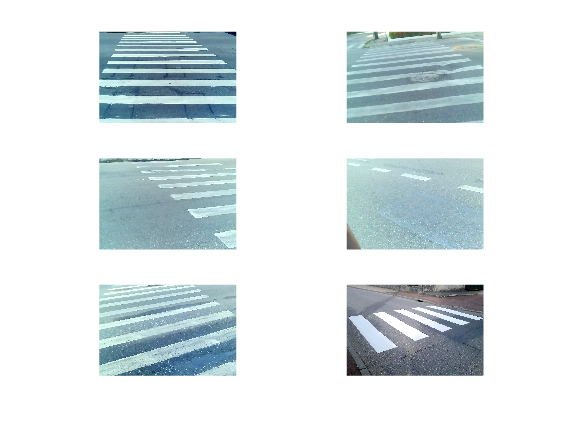

imlist = cell(6);
imlistgray = cell(6);
imlistbw = cell(6);

figure;
for i=1:6
    imlist{i} = imread("./part1 images/image" + i + ".jpg");

    imlist{i} = imresize(imlist{i}, [720 1080]);

    subplot(3,2,i)
    imshow(imlist{i})
end

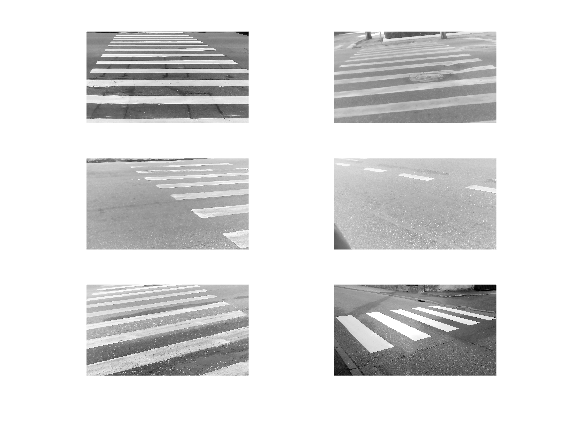

figure;
for i = 1:6
    imlistgray{i} = imresize(imlist{i},[720,1280]);

    if size(imlistgray{i}, 3) == 3
        imlistgray{i} = rgb2gray(imlistgray{i});
    else
        imlistgray{i} = imlistgray{i};
    end

    subplot(3,2,i)
    imshow(imlistgray{i})
end

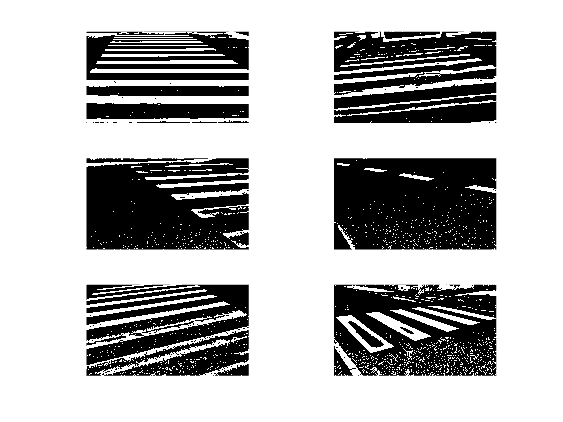


figure;
for i=1:6
    imlistbw{i} = imbinarize(imlistgray{i}, 'adaptive');
    
    subplot(3,2,i)
    imshow(imlistbw{i});
end

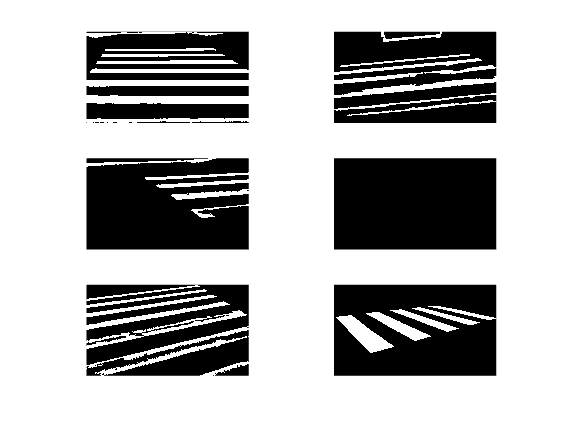

figure;
for i = 1:6
    imlistbw{i} = bwareaopen(imlistbw{i}, 10000);
    imlistbw{i} = imfill(imlistbw{i}, 'holes');

    subplot(3,2,i)
    imshow(imlistbw{i})
end

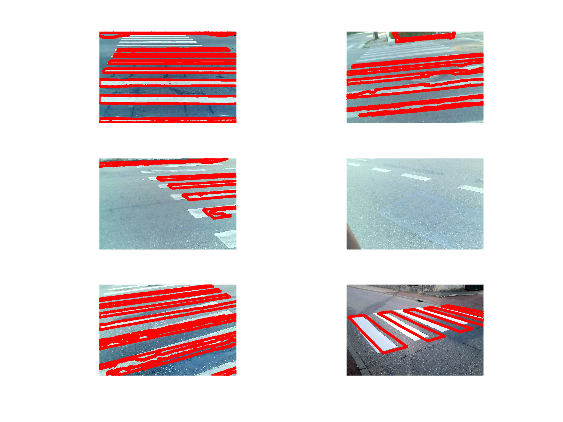

figure;
for i = 1:6
    B = bwboundaries(imlistbw{i});
    
    subplot(3,2,i)
    imshow(imlist{i})
    
    hold on;
    for k = 1:length(B)
       boundary = B{k};
       plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2)
    end
    hold off;
end